% Script to load and interrogate Mankoff (2020) subglacial discharge data
% Emma Cameron
% 12.05.2026

%% Paths
dataDir = "C:\Users\efc4\OneDrive - University of St Andrews\Desktop\PhD\umq_fjords\data\raw\mankoff2020_v8.0\discharge"

dataDir = "C:\Users\efc4\OneDrive - University of St Andrews\Desktop\PhD\umq_fjords\data\raw\mankoff2020_v8.0\discharge"

file = fullfile(dataDir,'RACMO_2024.nc');

%% Inspect file
ncdisp(file)

Source:
           C:\Users\efc4\OneDrive - University of St Andrews\Desktop\PhD\umq_fjords\data\raw\mankoff2020_v8.0\discharge\RACMO_2024.nc
Format:
           netcdf4
Global Attributes:
           keywords                     = 'GCMDSK:EARTH SCIENCE > CRYOSPHERE > GLACIERS/ICE SHEETS > ICE SHEETS > ICE SHEET MEASUREMENTS, GCMDSK:EARTH SCIENCE > CRYOSPHERE > GLACIERS/ICE SHEETS > GLACIER MASS BALANCE/ICE SHEET MASS BALANCE, GCMDSK:EARTH SCIENCE > CLIMATE INDICATORS > ATMOSPHERIC/OCEAN INDICATORS > FRESH WATER RIVER DISCHARGE, GCMDSK:EARTH SCIENCE > TERRESTRIAL HYDROSPHERE > SURFACE WATER > SURFACE WATER PROCESSES/MEASUREMENTS > DISCHARGE/FLOW, GCMDSK:EARTH SCIENCE > TERRESTRIAL HYDROSPHERE > SURFACE WATER > SURFACE WATER PROCESSES/MEASUREMENTS > DISCHARGE/FLOW > FLOW VELOCITY'
           keywords_vocabulary          = 'GCMDSK:GCMD Science Keywords:https://gcmd.earthdata.nasa.gov/kms/concepts/concept_scheme/sciencekeywords'
           id                           = 'dk.geus.promice:eff


%% Read discharge
Q = ncread(file,'discharge');
outlet = ncread(file, 'station'); %outlet ID can be found in QGIS
lat = ncread(file, 'lat');
lon = ncread(file, 'lon');
M2019 = ncread(file, 'M2019_ID') %store is M2019_ID 9

M2019 = 23898×1 int32 column vector
   227
   227
   227
   227
   227
   227
   227
   227
   227
   227
   227
   227
   227
   227
   227


%% Find stations belonging to M2019 basin 9
idx = find(M2019 == 9);

%% Check how many stations
length(idx)

ans = 6

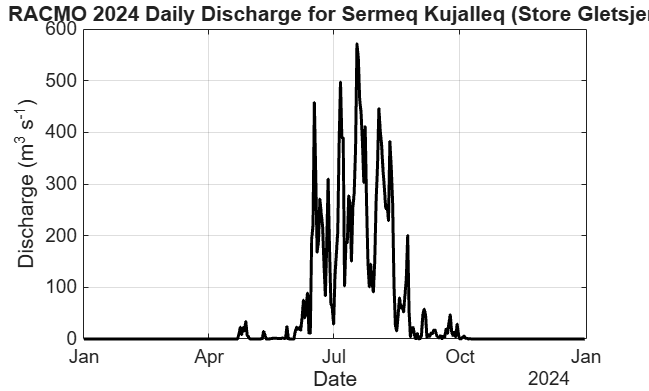


%% Extract discharge
q = Q(:,idx);

%% Sum all stations into one total discharge series
q_total = sum(q,2,'omitnan');

%% Read time
time = ncread(file,'time');

%% Convert to datetime
t = datetime(2024,1,1) + days(time);

%% Plot
figure

plot(t,q_total,'LineWidth',1.5, Color="k")

xlabel('Date')
ylabel('Discharge (m^3 s^{-1})')
title(['RACMO 2024 Daily Discharge for Sermeq Kujalleq (Store Gletsjer)'])

grid on

## Create FjordRPM subglacial discharge forcing

% FjordRPM expects row vectors

f.tsg = day(t,'dayofyear')';   % 1 x nt

f.Qsg = q_total';              % 1 x nt

%% Check dimensions
size(f.tsg)

ans =      1   366


size(f.Qsg)

ans =      1   366


saveDir = "C:\Users\efc4\OneDrive - University of St Andrews\Desktop\PhD\umq_fjords\data\processed"

saveDir = "C:\Users\efc4\OneDrive - University of St Andrews\Desktop\PhD\umq_fjords\data\processed"

saveFile = fullfile(saveDir,'Store_Qsg_2024.mat');
save(saveFile, 'f')
